
clear;


clockTimeLimit = 100; % 体験時間 (s)
period = 4; % 歩行周期 (s)

legForwardTimeRate = 2; % 足スライダ前進 時間比
legBackwardTimeRate = 3; % 足スライダ後退 時間比

stockForwardTimeRate = 3; % ストックスライダ前進 時間比
stockBackwardTimeRate = 4; % ストックスライダ後退 時間比

upTimeRate = 1; % 伸縮 持ち上げ 時間比
downTimeRate = 1; % 伸縮 降下 時間比

stockFlyingTimeRate = 3; % ストック空中時間比
stockGroundTimeRate = 4; % ストック接地時間比

tiltBackwardTimeRate = 3;
tiltForwardTimeRate = 4;

liftLength = 50; % 椅子 リフト長 単位 (mm)
pedalLength = 60; % ペダル長 単位 (mm)
seatSlideForwardLength = 200; % 椅子 スライド長 単位 (mm)
seatSlideBackwardLength = 25; % 椅子 スライド長 単位 (mm)
extendLength = 200; % 伸縮長 単位 (mm)
stockSlideForwardLength = 50; % ストック スライド前方向長 単位 (mm)
stockSlideBackwardLength = 250; % ストック スライド後方向長 単位 (mm)
tiltBackwardDeg = 1; % ストック 後傾角度 (deg)
tiltForwardDeg = -15; % ストック 前傾角度 (deg)

stockStartTime = period/2 + period*legForwardTimeRate/(legForwardTimeRate * legBackwardTimeRate)*1/4;

椅子 リフト

L = liftLength; % スライド長 単位 (mm)
startClockTime = 0; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

lifter = table(clockTime, deltaTime, absolutePosition, useStiffness)

lifter = 51×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         0          1.6              50                0      
       1.6          2.4               0                0      
         4          1.6              50                0      
       5.6          2.4               0                0      
         8          1.6              50                0      
       9.6          2.4               0                0      
        12          1.6              50                0      
      13.6          2.4               0                0      
        16          1.6              50                0      
      17.6          2.4               0                0      
        20          1.6              50                0      
      21.6          2.4               0                0      
        24          1.6              50                0      
      25.6          2.4           

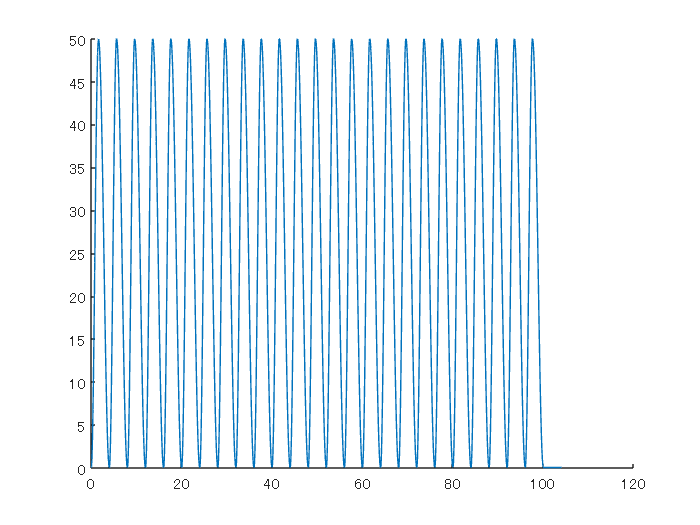

writetable(lifter, "lifter.csv");
figure;
[lifter_x, lifter_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ペダル

L = pedalLength; % スライド長 単位 (mm)
startClockTime = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 開始時刻 (s)
clockTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
clockTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)*3/4; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

leftPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftPedal = 51×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       2.8          1.2              60                0      
         4          1.2               0                0      
       6.8          1.2              60                0      
         8          1.2               0                0      
      10.8          1.2              60                0      
        12          1.2               0                0      
      14.8          1.2              60                0      
        16          1.2               0                0      
      18.8          1.2              60                0      
        20          1.2               0                0      
      22.8          1.2              60                0      
        24          1.2               0                0      
      26.8          1.2              60                0      
        28          1.2        

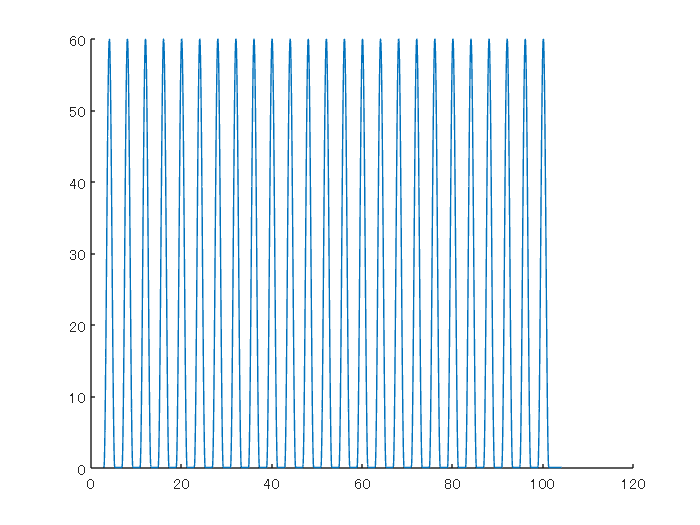

writetable(leftPedal, "leftPedal.csv");
figure;
[leftPedal_x, leftPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ペダル

L = pedalLength; % スライド長 単位 (mm)
startClockTime = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) + period/2; % 開始時刻 (s)
clockTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
clockTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)*3/4; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

rightPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightPedal = 49×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       4.8          1.2              60                0      
         6          1.2               0                0      
       8.8          1.2              60                0      
        10          1.2               0                0      
      12.8          1.2              60                0      
        14          1.2               0                0      
      16.8          1.2              60                0      
        18          1.2               0                0      
      20.8          1.2              60                0      
        22          1.2               0                0      
      24.8          1.2              60                0      
        26          1.2               0                0      
      28.8          1.2              60                0      
        30          1.2       

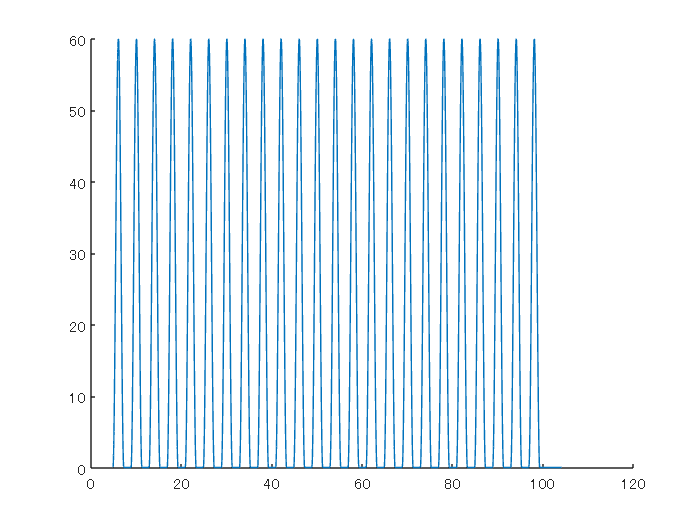

writetable(rightPedal, "rightPedal.csv");
figure;
[rightPedal_x, rightPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　左　スライダ

startClockTime = 0; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
clockTimeBB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) + period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeBB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionF = seatSlideForwardLength; % 単位 (mm)
positionB = 0.5*seatSlideForwardLength - 0.5*seatSlideBackwardLength; % 単位 (mm)
positionBB = -seatSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeBBList = (startClockTime + clockTimeBB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList), length(clockTimeBBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList), length(clockTimeBBList)]));
clockTimeBBList = clockTimeBBList(1:min([length(clockTimeFList), length(clockTimeBList), length(clockTimeBBList)]));
% tmp = [clockTimeFList; clockTimeBList; clockTimeBBList];
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
deltaTimeBBList = deltaTimeBB + 0*clockTimeBBList;
% tmp = [deltaTimeFList; deltaTimeBList; deltaTimeBBList];
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
positionBBList = positionBB + 0*clockTimeBBList;
% tmp = [positionFList; positionBList; positionBBList];
tmp = [positionFList; positionBBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

seatLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatLeftSlider = 51×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         0          1.6             200                0      
       1.6          2.4             -25                0      
         4          1.6             200                0      
       5.6          2.4             -25                0      
         8          1.6             200                0      
       9.6          2.4             -25                0      
        12          1.6             200                0      
      13.6          2.4             -25                0      
        16          1.6             200                0      
      17.6          2.4             -25                0      
        20          1.6             200                0      
      21.6          2.4             -25                0      
        24          1.6             200                0      
      25.6          2.4   

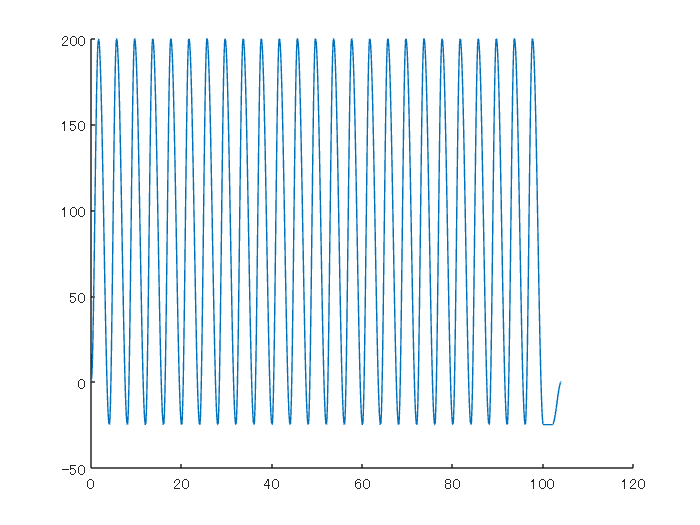

writetable(seatLeftSlider, "seatLeftSlider.csv");
figure;
[seatLeftSlider_x, seatLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　右　スライダ

startClockTime = period/2; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
clockTimeBB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) + period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeBB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionF = seatSlideForwardLength; % 単位 (mm)
positionB = 0.5*seatSlideForwardLength - 0.5*seatSlideBackwardLength; % 単位 (mm)
positionBB = -seatSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeBBList = (startClockTime + clockTimeBB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList), length(clockTimeBBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList), length(clockTimeBBList)]));
clockTimeBBList = clockTimeBBList(1:min([length(clockTimeFList), length(clockTimeBList), length(clockTimeBBList)]));
% tmp = [clockTimeFList; clockTimeBList; clockTimeBBList];
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
deltaTimeBBList = deltaTimeBB + 0*clockTimeBBList;
% tmp = [deltaTimeFList; deltaTimeBList; deltaTimeBBList];
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
positionBBList = positionBB + 0*clockTimeBBList;
% tmp = [positionFList; positionBList; positionBBList];
tmp = [positionFList; positionBBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

seatRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatRightSlider = 49×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         2          1.6             200                0      
       3.6          2.4             -25                0      
         6          1.6             200                0      
       7.6          2.4             -25                0      
        10          1.6             200                0      
      11.6          2.4             -25                0      
        14          1.6             200                0      
      15.6          2.4             -25                0      
        18          1.6             200                0      
      19.6          2.4             -25                0      
        22          1.6             200                0      
      23.6          2.4             -25                0      
        26          1.6             200                0      
      27.6          2.4  

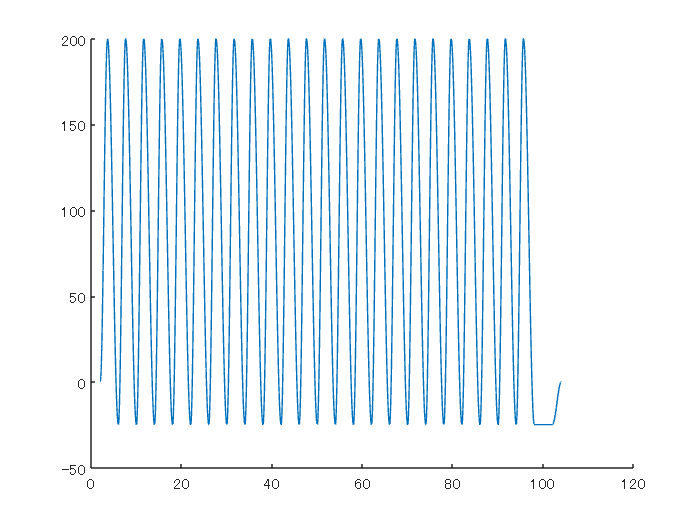

writetable(seatRightSlider, "seatRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatRightSlider_x, seatRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);


L = extendLength; % スライド長 単位 (mm)
startClockTime = stockStartTime; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
clockTimeSlowD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) + 0.1; % 単位 (s)
deltaTimeU = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeSlowD = period*stockGroundTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) - 0.1; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 2*L/3; % 単位 (mm)
positionSlowD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeSlowDList = (startClockTime + clockTimeSlowD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
clockTimeSlowDList = clockTimeSlowDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
tmp = [clockTimeUList; clockTimeDList; clockTimeSlowDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
deltaTimeSlowDList = deltaTimeSlowD + 0*clockTimeSlowDList;
tmp = [deltaTimeUList; deltaTimeDList; deltaTimeSlowDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
positionSlowDList = positionSlowD + 0*clockTimeSlowDList;
tmp = [positionUList; positionDList; positionSlowDList];
absolutePosition = tmp(:);

tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList)); zeros(size(clockTimeSlowDList));];
useStiffness = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;
useStiffness(end+1) = 0;

stockLeftExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftExtend = 73×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     2.3333       0.85714             200              0      
     3.1905       0.85714          133.33              1      
     4.1476        2.1857               0              0      
     6.3333       0.85714             200              0      
     7.1905       0.85714          133.33              1      
     8.1476        2.1857               0              0      
     10.333       0.85714             200              0      
      11.19       0.85714          133.33              1      
     12.148        2.1857               0              0      
     14.333       0.85714             200              0      
      15.19       0.85714          133.33              1      
     16.148        2.1857               0              0      
     18.333       0.85714             200              0      
      19.19       0.85714

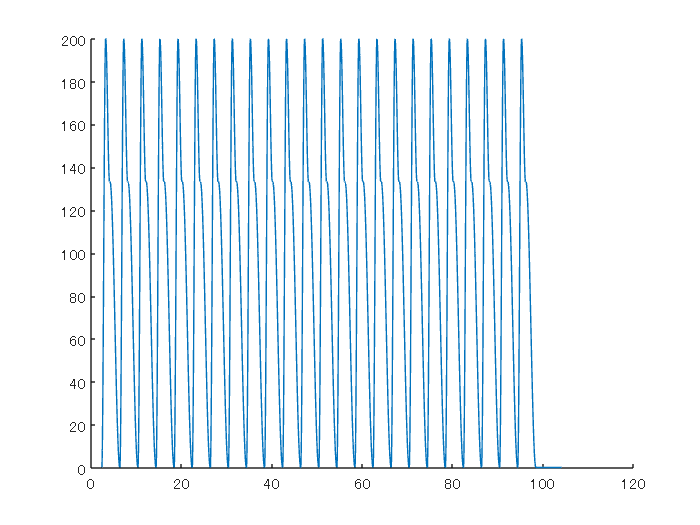

writetable(stockLeftExtend, "stockLeftExtend.csv");
figure;
[stockLeftExtend_x, stockLeftExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックの伸縮


L = extendLength; % スライド長 単位 (mm)
startClockTime = stockStartTime; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
clockTimeSlowD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) + 0.1; % 単位 (s)
deltaTimeU = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeSlowD = period*stockGroundTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) - 0.1; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 2*L/3; % 単位 (mm)
positionSlowD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeSlowDList = (startClockTime + clockTimeSlowD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
clockTimeSlowDList = clockTimeSlowDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
tmp = [clockTimeUList; clockTimeDList; clockTimeSlowDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
deltaTimeSlowDList = deltaTimeSlowD + 0*clockTimeSlowDList;
tmp = [deltaTimeUList; deltaTimeDList; deltaTimeSlowDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
positionSlowDList = positionSlowD + 0*clockTimeSlowDList;
tmp = [positionUList; positionDList; positionSlowDList];
absolutePosition = tmp(:);
tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList)); zeros(size(clockTimeSlowDList));];
useStiffness = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;
useStiffness(end+1) = 0;

stockRightExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockRightExtend = 73×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     2.3333       0.85714             200              0      
     3.1905       0.85714          133.33              1      
     4.1476        2.1857               0              0      
     6.3333       0.85714             200              0      
     7.1905       0.85714          133.33              1      
     8.1476        2.1857               0              0      
     10.333       0.85714             200              0      
      11.19       0.85714          133.33              1      
     12.148        2.1857               0              0      
     14.333       0.85714             200              0      
      15.19       0.85714          133.33              1      
     16.148        2.1857               0              0      
     18.333       0.85714             200              0      
      19.19       0.8571

writetable(stockRightExtend, "stockRightExtend.csv");
figure;
[stockRightExtend_x, stockRightExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストックのスライダ

startClockTime = stockStartTime; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionF = stockSlideForwardLength; % 単位 (mm)
positionB = -stockSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

stockLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftSlider = 49×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     2.3333       1.7143              50               0      
     4.0476       2.2857            -250               0      
     6.3333       1.7143              50               0      
     8.0476       2.2857            -250               0      
     10.333       1.7143              50               0      
     12.048       2.2857            -250               0      
     14.333       1.7143              50               0      
     16.048       2.2857            -250               0      
     18.333       1.7143              50               0      
     20.048       2.2857            -250               0      
     22.333       1.7143              50               0      
     24.048       2.2857            -250               0      
     26.333       1.7143              50               0      
     28.048       2.2857 

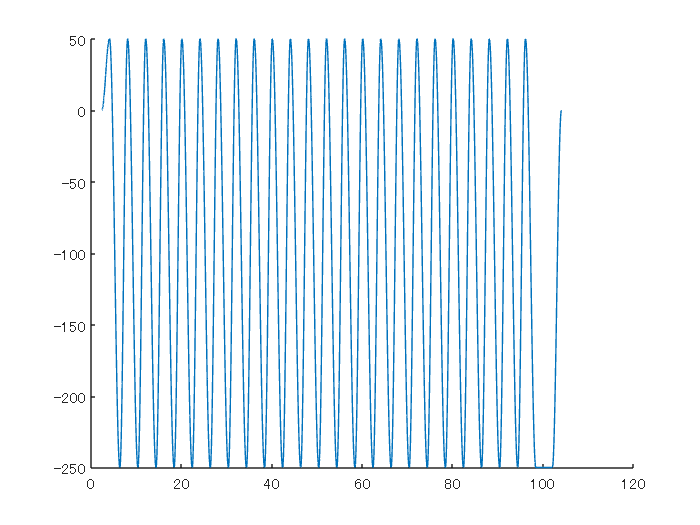

writetable(stockLeftSlider, "stockLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockLeftSlider_x, stockLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックのスライダ


L = stockSlideForwardLength; % スライド長 単位 (mm)
startClockTime = stockStartTime; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionF = stockSlideForwardLength; % 単位 (mm)
positionB = -stockSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

stockRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockRightSlider = 49×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     2.3333       1.7143              50               0      
     4.0476       2.2857            -250               0      
     6.3333       1.7143              50               0      
     8.0476       2.2857            -250               0      
     10.333       1.7143              50               0      
     12.048       2.2857            -250               0      
     14.333       1.7143              50               0      
     16.048       2.2857            -250               0      
     18.333       1.7143              50               0      
     20.048       2.2857            -250               0      
     22.333       1.7143              50               0      
     24.048       2.2857            -250               0      
     26.333       1.7143              50               0      
     28.048       2.2857

writetable(stockRightSlider, "stockRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockRightSlider_x, stockRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTimeLeftTilt = stockStartTime; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
leftTiltDeltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
leftTiltDeltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate)*1/2; % 単位 (s)
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTimeLeftTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTimeLeftTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = leftTiltDeltaTimeB + 0*clockTimeBList;
deltaTimeFList = leftTiltDeltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

leftTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftTilt = 49×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     2.3333       1.7143              1                0      
     4.0476       1.1429            -15                0      
     6.3333       1.7143              1                0      
     8.0476       1.1429            -15                0      
     10.333       1.7143              1                0      
     12.048       1.1429            -15                0      
     14.333       1.7143              1                0      
     16.048       1.1429            -15                0      
     18.333       1.7143              1                0      
     20.048       1.1429            -15                0      
     22.333       1.7143              1                0      
     24.048       1.1429            -15                0      
     26.333       1.7143              1                0      
     28.048       1.1429        

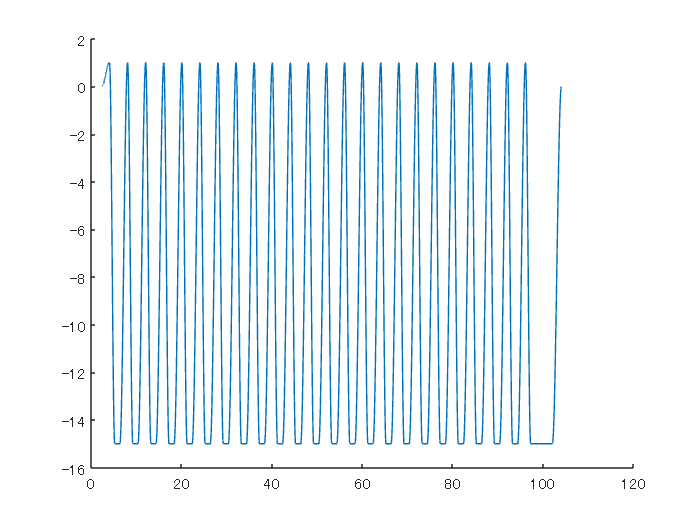

writetable(leftTilt, "leftTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[leftTilt_x, leftTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTimeRightTilt = stockStartTime; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
rightTiltDeltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
rightTiltDeltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate)*1/2; % 単位 (s)
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTimeRightTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTimeRightTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = rightTiltDeltaTimeB + 0*clockTimeBList;
deltaTimeFList = rightTiltDeltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

rightTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightTilt = 49×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     2.3333       1.7143              1                0      
     4.0476       1.1429            -15                0      
     6.3333       1.7143              1                0      
     8.0476       1.1429            -15                0      
     10.333       1.7143              1                0      
     12.048       1.1429            -15                0      
     14.333       1.7143              1                0      
     16.048       1.1429            -15                0      
     18.333       1.7143              1                0      
     20.048       1.1429            -15                0      
     22.333       1.7143              1                0      
     24.048       1.1429            -15                0      
     26.333       1.7143              1                0      
     28.048       1.1429       

writetable(rightTilt, "rightTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[rightTilt_x, rightTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

TiltCSV = table( ...
    period, tiltBackwardDeg, tiltForwardDeg, tiltBackwardTimeRate, tiltForwardTimeRate, startClockTimeLeftTilt, startClockTimeRightTilt, ...
    leftTiltDeltaTimeB, leftTiltDeltaTimeF, rightTiltDeltaTimeB, rightTiltDeltaTimeF ...
    )

TiltCSV = 1×11 table
    period    tiltBackwardDeg    tiltForwardDeg    tiltBackwardTimeRate    tiltForwardTimeRate    startClockTimeLeftTilt    startClockTimeRightTilt    leftTiltDeltaTimeB    leftTiltDeltaTimeF    rightTiltDeltaTimeB    rightTiltDeltaTimeF
    ______    _______________    ______________    ____________________    ___________________    ______________________    _______________________    __________________    __________________    ___________________    ___________________

      4              1                -15                   3                       4                     2.3333                    2.3333                   1.7143                1.1429                1.7143                 1.1429       


writetable(TiltCSV, 'tilt.csv');

signal_lifter = timeseries(lifter_x, lifter_t, Name='lifter');
signal_leftPedal = timeseries(leftPedal_x, leftPedal_t, Name='leftPedal');
signal_rightPedal = timeseries(rightPedal_x, rightPedal_t, Name='rightPedal');
signal_seatLeftSlider = timeseries(seatLeftSlider_x, seatLeftSlider_t, Name='seatLeftSlider');
signal_seatRightSlider = timeseries(seatRightSlider_x, seatRightSlider_t, Name='seatRightSlider');
signal_stockLeftSlider = timeseries(stockLeftSlider_x, stockLeftSlider_t, Name='stockLeftSlider');
signal_stockRightSlider = timeseries(stockRightSlider_x, stockRightSlider_t, Name='stockRightSlider');
signal_stockLeftExtend = timeseries(stockLeftExtend_x, stockLeftExtend_t, Name='stockLeftExtend');
signal_stockRightExtend = timeseries(stockRightExtend_x, stockRightExtend_t, Name='stockRightExtend');
signal_leftTilt = timeseries(leftTilt_x, leftTilt_t, Name="leftTilt");
signal_rightTilt = timeseries(rightTilt_x, rightTilt_t, Name="rightTilt");

Scenario = Simulink.SimulationData.Dataset;

Scenario{1} = signal_lifter;
Scenario{2} = signal_leftPedal;
Scenario{3} = signal_rightPedal;
Scenario{4} = signal_seatLeftSlider;
Scenario{5} = signal_seatRightSlider;
Scenario{6} = signal_stockLeftExtend;
Scenario{7} = signal_stockRightExtend;
Scenario{8} = signal_stockLeftSlider;
Scenario{9} = signal_stockRightSlider;
Scenario{10} = signal_leftTilt;
Scenario{11} = signal_rightTilt;


% Scenario{2} = SignalStickRightPitch;
% Scenario{2}.Name = 'SignalStickRightPitch';
% Scenario{5} = signal_stockLeftPitch;
% Scenario{5}.Name = 'SignalStickLeftPitch';

save('../../../scenario.mat', 'Scenario');

sim("Simulink.slx");

clear;

function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end